p = 0;
Cc = 0.61;
a = 0.6;
z1 = 5;
g = 9.81;
z2 = Cc .* a;

% (a)
az1 = a/z1

az1 = 0.1200

if (0.1 < az1) && (az1 < 0.2)
    p = z2 .* sqrt((2 .* g .* (z1 - z2))/(1 - (z2/z1).^2));
    fprintf('The flow rate per unit width is: %f\n', p)
else
    fprintf('Change the value of a = %f', a)
end

The flow rate per unit width is: 3.499252




% (b)

z1 = 5:0.25:15;
fprintf('z1             Q/b\n')

z1             Q/b



for i = 1:length(z1)
    q(i) = z2 .* sqrt((2 .* g .* (z1(i) - z2))/(1 - (z2/z1(i)).^2));
    fprintf('%d  %f      %f\n', i, z1(i), q(i))
end

1  5.000000      3.499252


2  5.250000      3.591504


3  5.500000      3.681478


4  5.750000      3.769335


5  6.000000      3.855214


6  6.250000      3.939244


7  6.500000      4.021537


8  6.750000      4.102196


9  7.000000      4.181314


10  7.250000      4.258975


11  7.500000      4.335257


12  7.750000      4.410230


13  8.000000      4.483959


14  8.250000      4.556503


15  8.500000      4.627918


16  8.750000      4.698254


17  9.000000      4.767558


18  9.250000      4.835875


19  9.500000      4.903245


20  9.750000      4.969707


21  10.000000      5.035296


22  10.250000      5.100045


23  10.500000      5.163986


24  10.750000      5.227148


25  11.000000      5.289559


26  11.250000      5.351245


27  11.500000      5.412230


28  11.750000      5.472538


29  12.000000      5.532192


30  12.250000      5.591210


31  12.500000      5.649615


32  12.750000      5.707423


33  13.000000      5.764654


34  13.250000      5.821323


35  13.500000      5.877447


36  13.750000      5.933043


37  14.000000      5.988123


38  14.250000      6.042702


39  14.500000      6.096794


40  14.750000      6.150411


41  15.000000      6.203566


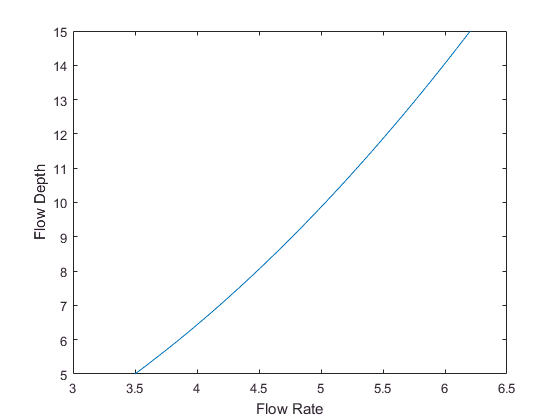


plot(q, z1)
xlabel('Flow Rate')
ylabel('Flow Depth')